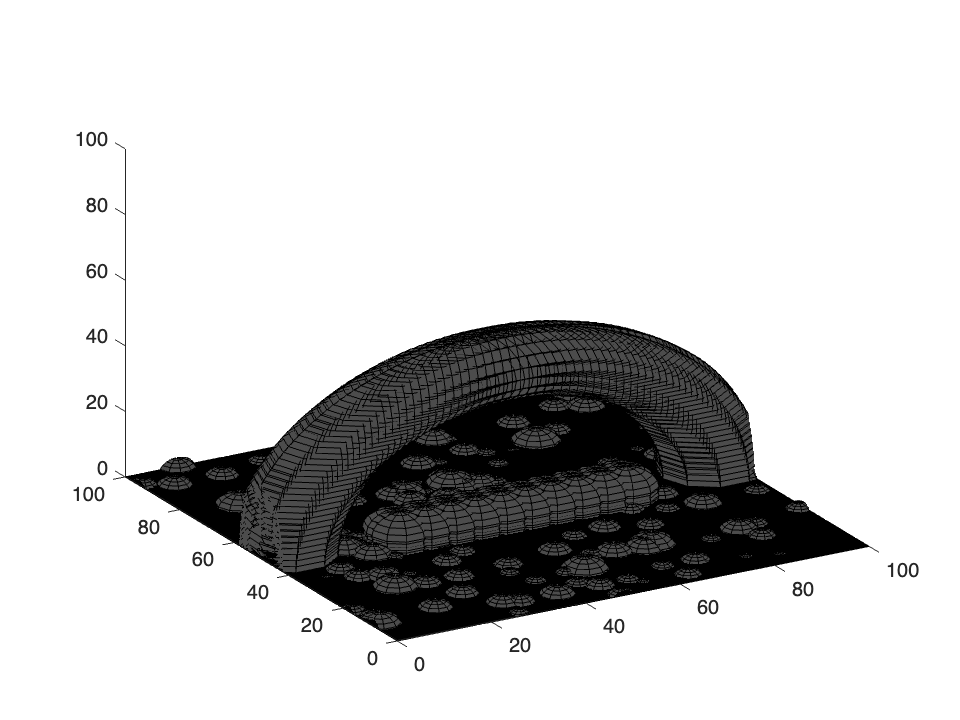

% Demonstration script for the 3D course planning software

% Create a new world and add an arch to it
space = world(100, 100, 100, Obstacle.empty);
space = add_arch(space, [50 50 0], 45, 80, 10);
space = add_terrain(space, 150, 3);
space = add_wall(space, 20, 80, 40, 50, -10, 10, 6);
plot_world(space);

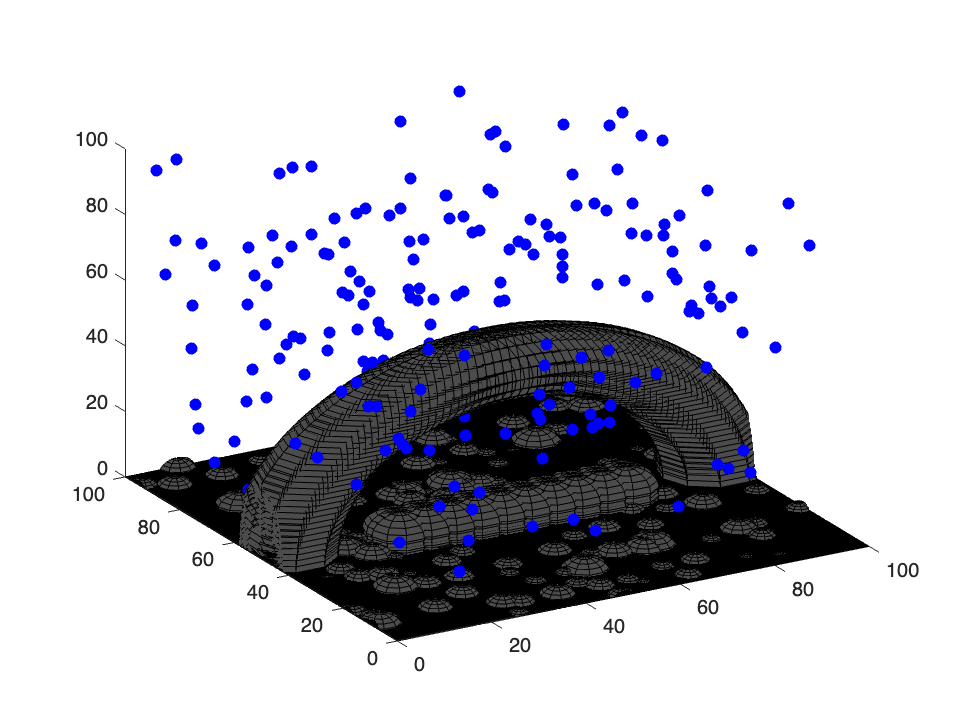


% Define the Helicopter dimension as a min clearance from obstacle
clearance = 5;

% Create a PRM planner over the space for the helicopter
planner = PRM(200, 10, space, clearance);

% Sample the space and populate the edges in the graph
u_sampled = sampler(planner);
show_sample(u_sampled);

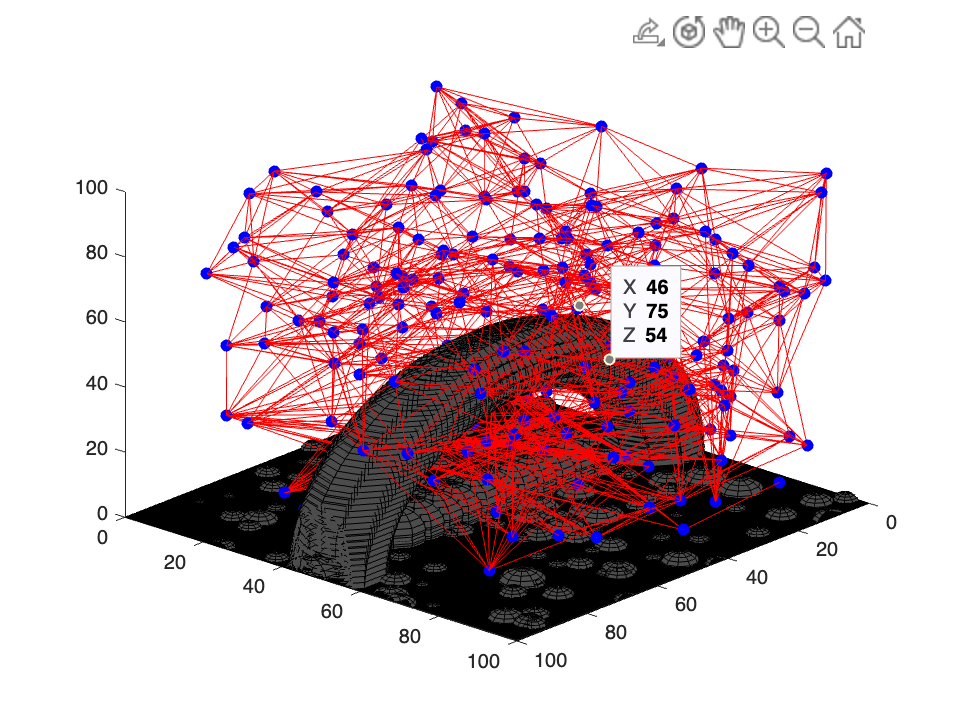

u_sampled = create_edges(u_sampled);
show_graph(u_sampled)


% Now make a copy of the planner in which we have solved for a path
start = [1 1 30];
goal = [80 80 30];
mapped = find_path(u_sampled, start, goal);

Error using PRM/find_path
~gunty


% Show the path
show_path(mapped);

% Do post-processing
mapped = post_process(mapped);
show_path(mapped);

% Try smoothing
mapped = smooth_path(mapped);
show_smooth(mapped);

% Now try an adaptive sampler
a_sampled = adaptive_sampler(planner, start, goal, 2);
show_sample(a_sampled);

% Connect up the graph
a_sampled = create_edges(a_sampled);
show_graph(a_sampled);

% Find a path from start to goal
mapped = find_path(a_sampled, start, goal);
show_path(mapped);

% Perform post-processing
mapped = post_process(mapped);
show_path(mapped);

% Try smoothing
mapped = smooth_path(mapped);
show_smooth(mapped);
